% Week 02 - In and After Class

clear all
fc = 28e9;
elvals = ( -90:2: 90)'; %91
azvals = (-180:2:180)'; %181
el_steps = length(elvals);
az_steps = length(azvals);
elvals_rad = elvals * pi / 180.;

## Compute the directivity 

## NOTE: This explanation was taken is from Prof. Sundeep's lab_uav_antenna

We next compute the directivity of the antenna. The directivity of the antenna is given by,

where Ptot is the total radiated power and U is the far-field radiation density

Hence, the directivity (in linear scale) is:

for some constant c. To compute the constant c, we know that the average of the directivity dir * cos(el) over a spherical integral must be one. Hence, if we take mean over the discrete values, you should have that:

You can use this relation to find the scale factor, c.

%Start with a dark Array
OnOffMat= zeros(el_steps,az_steps); %dirMat[el,az]
%And Create a bright square at the middle of the Array
el_min=(el_steps+1)/2-10;
el_max=(el_steps+1)/2+10;
az_min=(az_steps+1)/2 -5;
az_max=(az_steps+1)/2 +5;
OnOffMat(el_min:el_max, az_min:az_max)=1;

% Integration over el: dy=r*del         is     const for all (r,az,el)
% Integration over az: dx=r*daz*cos(el) is NOT const for all (r,az,el)
% dx*dy = (r*del) * (r*cos(el))*daz = r^2 * del * daz * cos(el)
% Think in terms of latitudes(el) vs longitudes(az) on Earth (same case)

OnOffMat_mean_az = mean(OnOffMat, 2); % axis=2=columns ... Like Python
const_c = mean(cos(elvals_rad)) / mean(OnOffMat_mean_az .* cos(elvals_rad));
fprintf("Calculated constant c=%e", const_c);

Calculated constant c=4.590823e+01

dirMat = const_c*OnOffMat;

% TODO: Print the maximum gain.
maxgain     = max(dirMat, [], 'all') % 'Python-like', or not ...

maxgain = 45.9082

maxgain_dbi = 10*log10(maxgain)

maxgain_dbi = 16.6189

fprintf("MAX Gain is %e (%f) dBi", maxgain, maxgain_dbi)

MAX Gain is 4.590823e+01 (16.618906) dBi

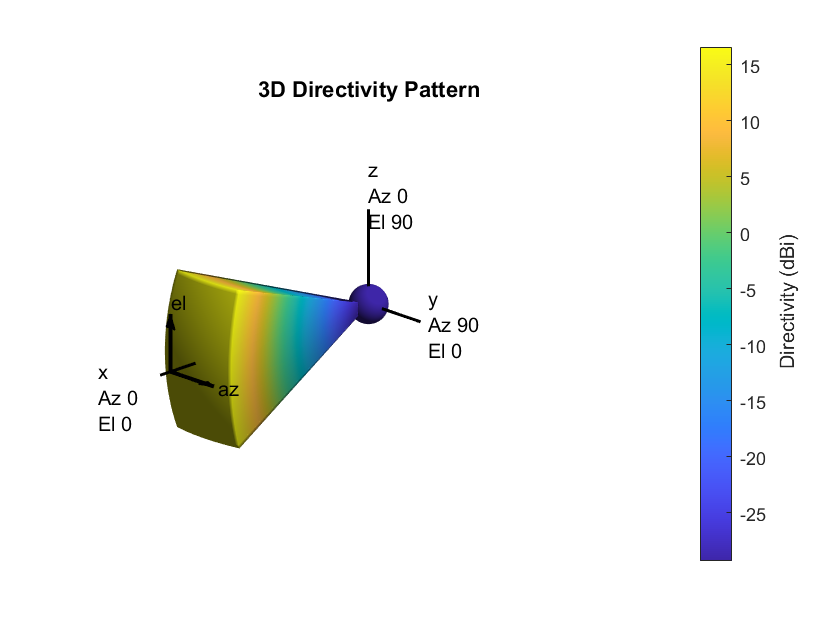

figure(1)
phasePattern = zeros(size(dirMat));
ant  = phased.CustomAntennaElement(...
    'AzimuthAngles'   , azvals,    ...
    'ElevationAngles' , elvals,    ...
    'MagnitudePattern', dirMat,    ...
    'PhasePattern'    , phasePattern);
ant.pattern(fc);

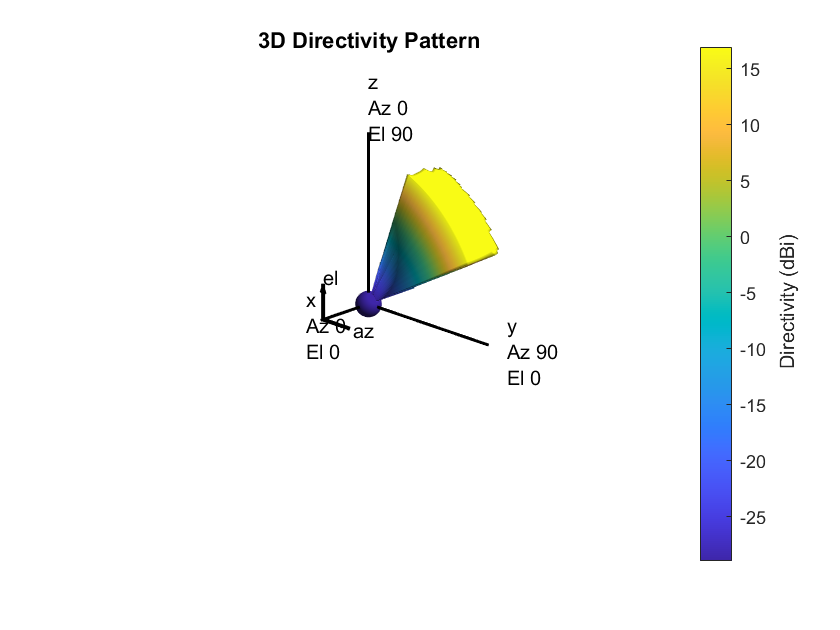


% figure(2)
% antenna1 = ant;
% pat = zeros(numel(elvals),numel(azvals),'like',1);
% for m = 1:numel(elvals)
%     temp = antenna1(fc,[azvals;elvals(m)*ones(1,numel(azvals))]);
%     pat(m,:) = temp;
% end
% imagesc(azvals,elvals,abs(pat))
% axis xy
% axis equal
% axis tight
% xlabel('Azimuth (deg)')
% ylabel('Elevation (deg)')
% title('Original Radiation Pattern')
% colorbar


newax = rotx(50)*rotz(100);
dirMat_rot  = rotpat(dirMat,azvals,elvals,newax);


figure(11)
ant  = phased.CustomAntennaElement(...
    'AzimuthAngles'   , azvals,    ...
    'ElevationAngles' , elvals,    ...
    'MagnitudePattern', dirMat_rot,    ...
    'PhasePattern'    , phasePattern);
ant.pattern(fc);

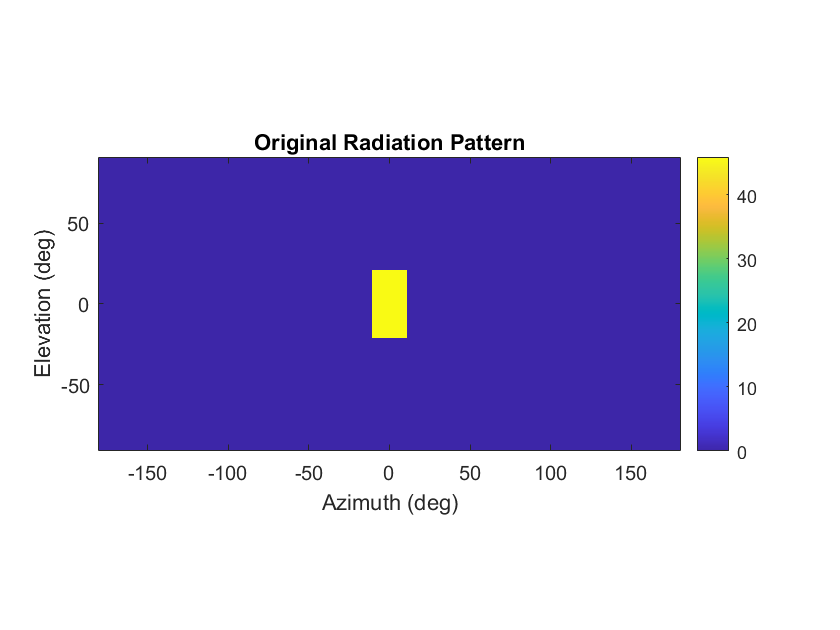


figure(3)
imagesc(azvals,elvals,abs(dirMat))
axis xy
axis equal
axis tight
xlabel('Azimuth (deg)')
ylabel('Elevation (deg)')
title('Original Radiation Pattern')
colorbar

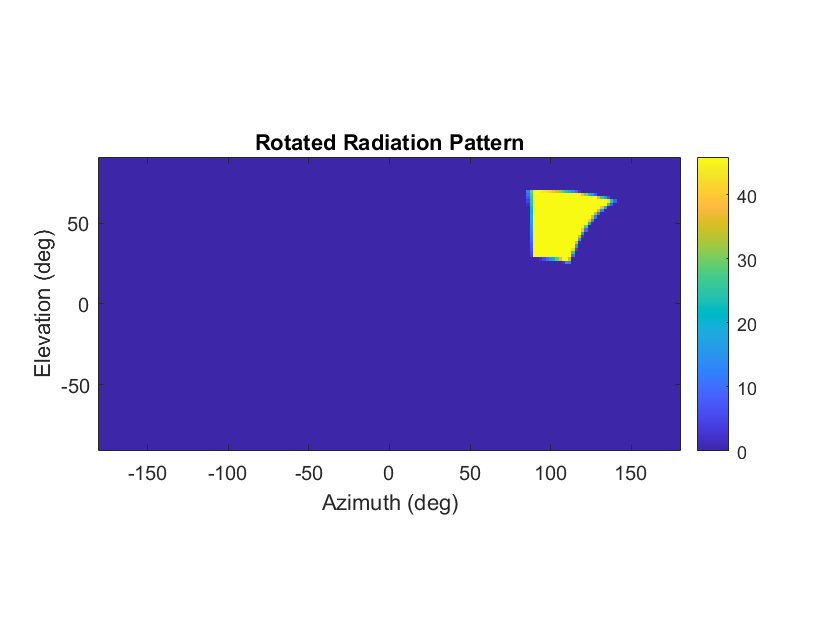


figure(12)
imagesc(azvals,elvals,abs(dirMat_rot))
axis xy
axis equal
axis tight
xlabel('Azimuth (deg)')
ylabel('Elevation (deg)')
title('Rotated Radiation Pattern')
colorbar